clear all;

N = 75;
xs = linspace(1,0,N)';
ys = 2*cos(2*pi*xs + 2) + (xs + 1); 
data = ys + normrnd(0,4,size(xs));

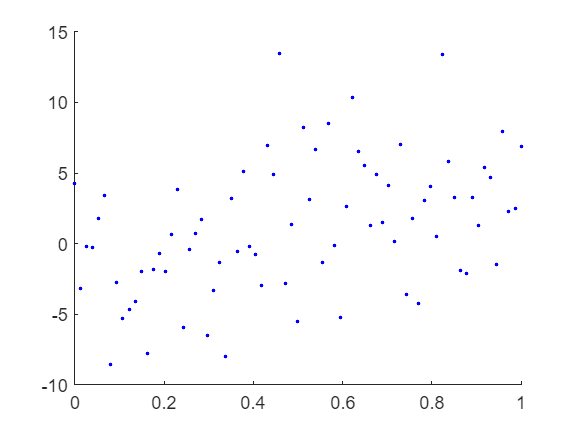

fig1 = figure(1);
clf(fig1,"reset");
hold on;
plot(xs, data, ".b");
hold off;

A = [ones(size(xs)) cos(2*pi*xs+2) xs];
c = A\data

c =    -0.7342
    1.7118
    3.7774


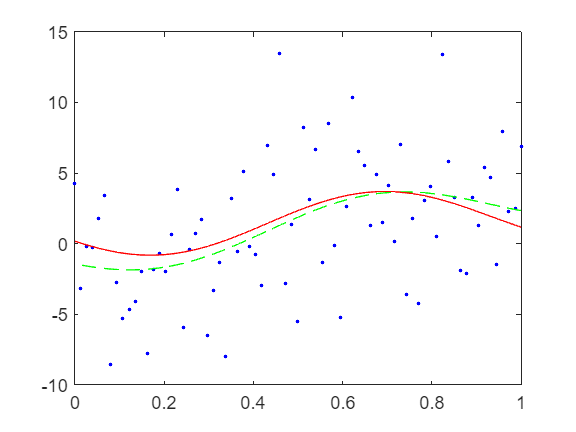

yys = A*c;

fig2 = figure(2);
clf(fig2,"reset");
plot(xs, data, ".b");
hold on;
plot(xs, yys, "--g");
plot(xs, ys, "-r");
hold off;